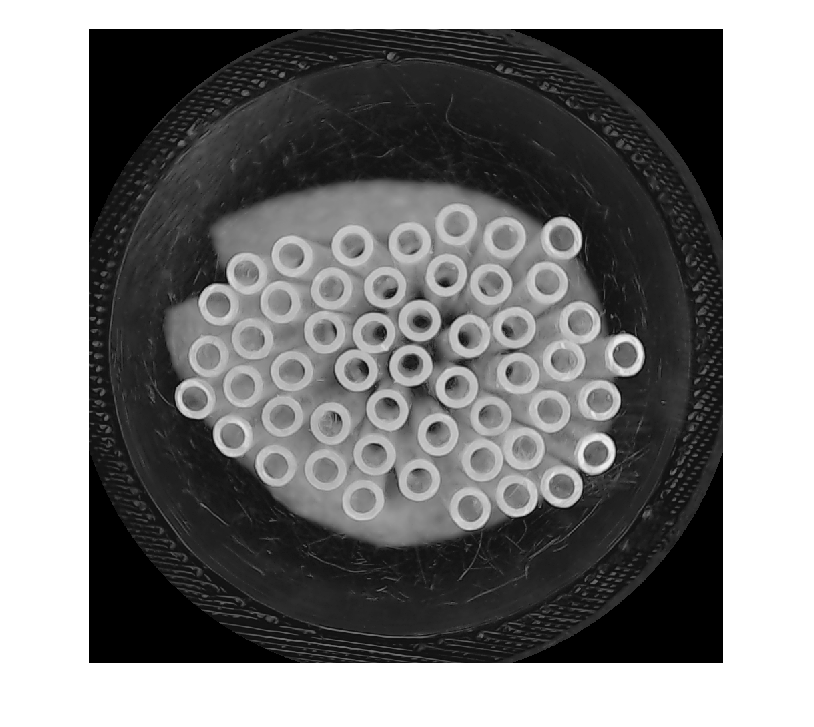

clear all; close all;

img = imread('needles_50.png');
img = rgb2gray(img);
imshow(img);

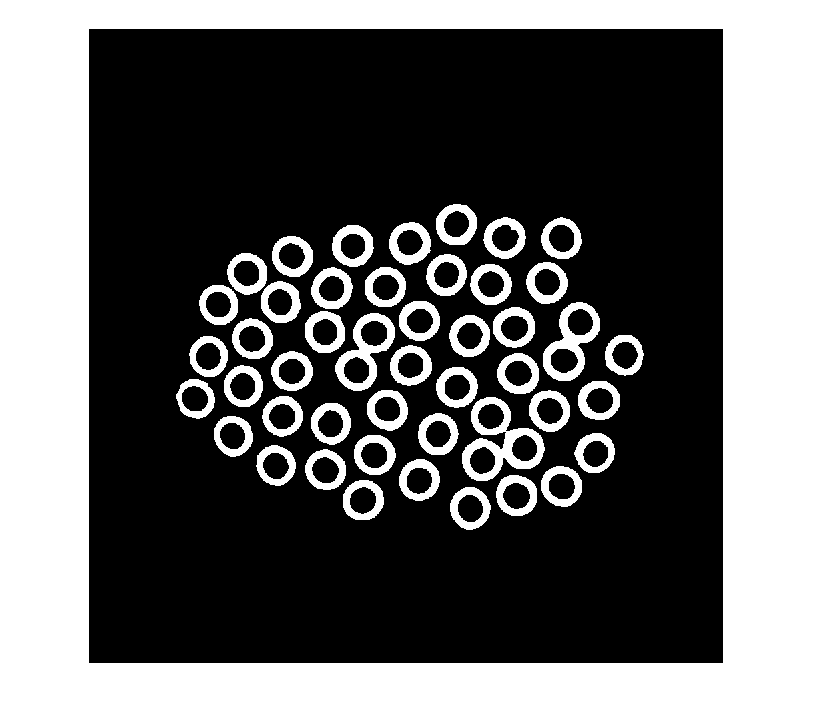


%--------------------
% Binarize to get circles
imgBina = img > 167;
% Remove noise
imgBina = medfilt2(imgBina, [7,7]);
imshow(imgBina);

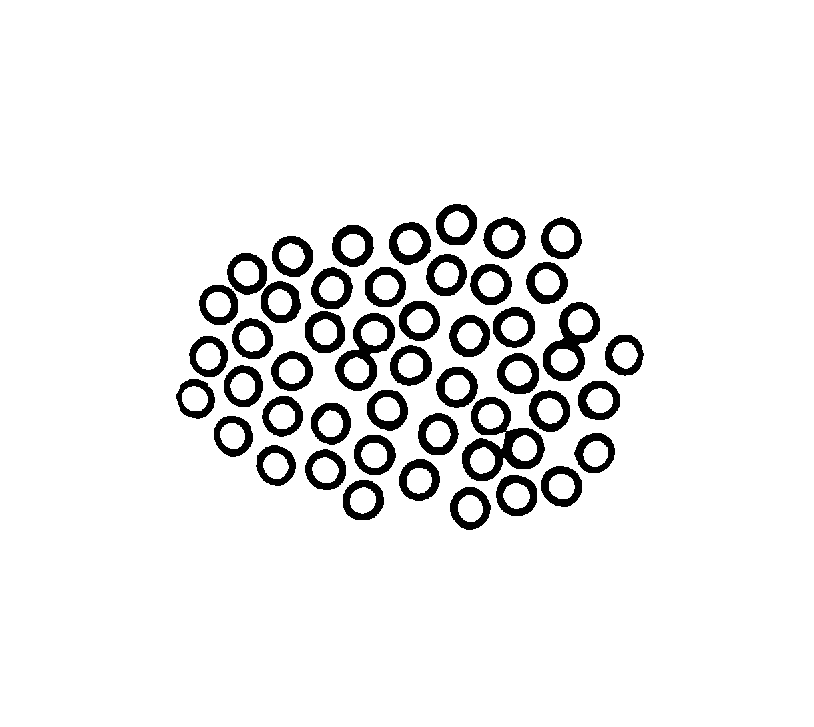


% Invert and then count white objects
% The number of needles is the number of white object
% minus 1 (which is background)
invert = 1 - imgBina;
imshow(invert);

[L,count] = bwlabel(invert);
n = count-1;

%--------------------
fprintf('The number of needles is: %d', n);

The number of needles is: 50